## Colors for plotting

demand_color = [83 81 84] / 255;
gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

# Benchmarking -- MOUC for VRE sources

% Span for uniform weights
span = 0.01:0.01:0.99;

% Placeholders for costs, runtimes and relaxation losses
cost_gurobi = zeros(length(span), 2);
runtime_gurobi = zeros(1, length(span));
cost_sedumi = zeros(length(span), 2);
runtime_sedumi = zeros(1, length(span));
objective_gurobi = zeros(1, length(span));
loss = zeros(1, length(span));

% Penalty
alpha = 25;

% Network and schedule size
Nconv = 3;
T = 6;

% Load a network into the workspace
network = network_init(Nconv, T);

## Plotting the generated network demand

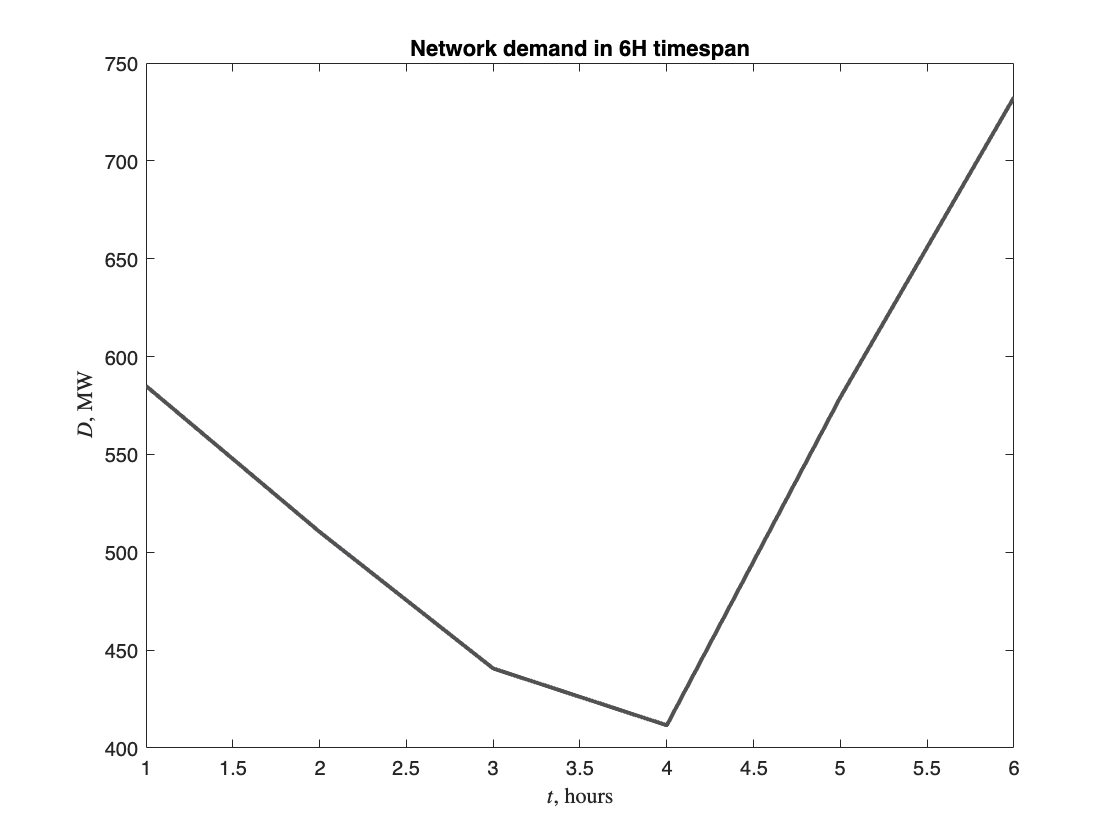

figure();
plot(1:1:T, network.demand, LineWidth=2, Color=demand_color);
title(sprintf('Network demand in %dH timespan', T))
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');

## Run computations for the above network, different weights

#### !!! This part of code runs for multiple hours. Please consider before running it yourself.

for i = 1:length(span)

    % Assign weights
    w2 = span(i);
    w1 = 1 - w2;

    % Iteration index (to not get lost)
    fprintf('Iteration %d: w1=%d, w2=%d\n', i, w1, w2);

    % Objective scalarization
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;

    % Solve and extract runtimes (Gurobi, Sedumi)
    result_gurobi = solve_gurobi(network);
    runtime_gurobi(i) = result_gurobi.runtime;
    [result_sedumi, runtime_sedumi(i)] = solve_sedumi(network);

    % Extract two objectives
    [cost_gurobi(i, 1), cost_gurobi(i, 2)] = objective_values(network, alpha, result_gurobi.x);
    [cost_sedumi(i, 1), cost_sedumi(i, 2)] = objective_values(network, alpha, result_sedumi);
    
    % Compute MAE (and scalarized Gurobi objective for reference later)
    objective_gurobi(i) = result_gurobi.objval;
    loss(i) = sum(abs(result_gurobi.x - result_sedumi));
end

% Complete MAE
loss = loss/length(loss);

## Plot MAE (absolute, %)

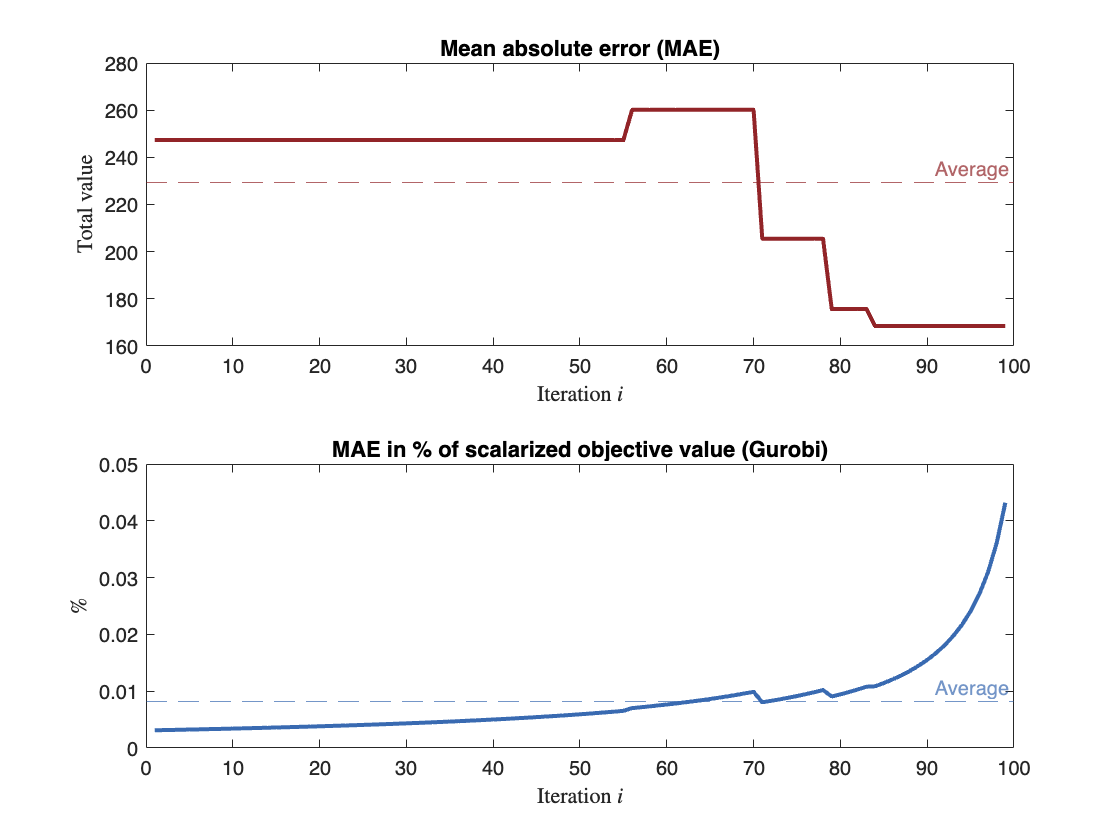

% Tiles for plot
tiledlayout(2,1);

% Absolute
nexttile
plot(1:1:length(runtime_gurobi), loss, 'Color', gurobi_color, LineWidth=2); hold on
yline(mean(loss),'--','Average', Color=gurobi_color); hold off
title('Mean absolute error (MAE)');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('Total value', 'Interpreter','latex');

% Percent
nexttile
plot(1:1:length(runtime_sedumi), loss./objective_gurobi, 'Color', sedumi_color, LineWidth=2); hold on
yline(mean(loss./objective_gurobi),'--','Average', Color=sedumi_color); hold off
title('MAE in % of scalarized objective value (Gurobi)');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('\%', 'Interpreter', 'latex');

## Plot achieved Pareto fronts

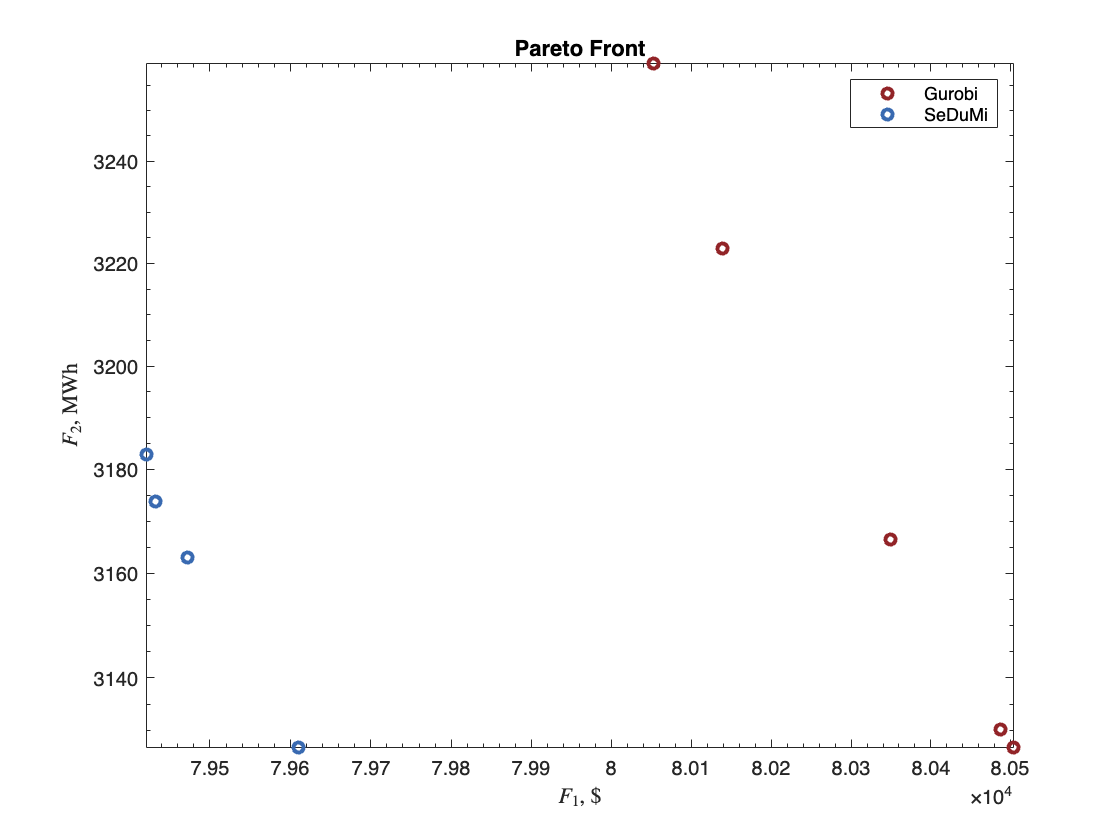

figure();
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2),'o', 'MarkerSize', 5, 'Color', gurobi_color, 'LineWidth', 2); hold on
loglog(cost_sedumi(:, 1), cost_sedumi(:, 2), 'o', 'MarkerSize', 5, 'Color', sedumi_color, 'LineWidth', 2); hold off
title('Pareto Front');
legend('Gurobi', 'SeDuMi');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

## Plot runtimes

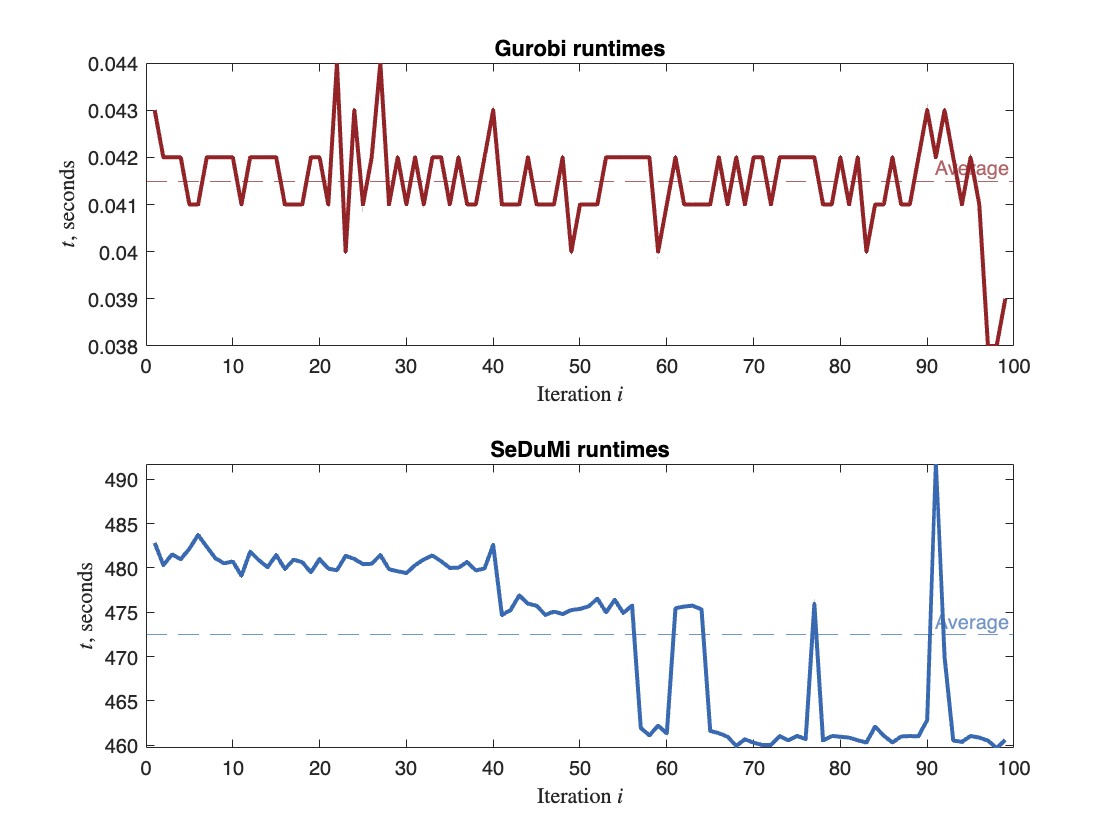

tiledlayout(2,1);

% Gurobi
nexttile
plot(1:1:length(runtime_gurobi), runtime_gurobi, 'Color', gurobi_color, LineWidth=2); hold on
yline(mean(runtime_gurobi),'--','Average', Color=gurobi_color); hold off
title('Gurobi runtimes');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');

% SeDuMi
nexttile
plot(1:1:length(runtime_sedumi), runtime_sedumi, 'Color', sedumi_color, LineWidth=2);hold on
yline(mean(runtime_sedumi),'--','Average', Color=sedumi_color); hold off
title('SeDuMi runtimes');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');

## Experiment with Gurobi (due to computational load)

#### Influence of penalty

% Span for uniform weights
span_pen = 0.01:0.01:0.99;

% Span for penalties
pens = [0, 25, 250];

% Placeholder variables
cost_gurobi_pen = zeros(length(span), 2);

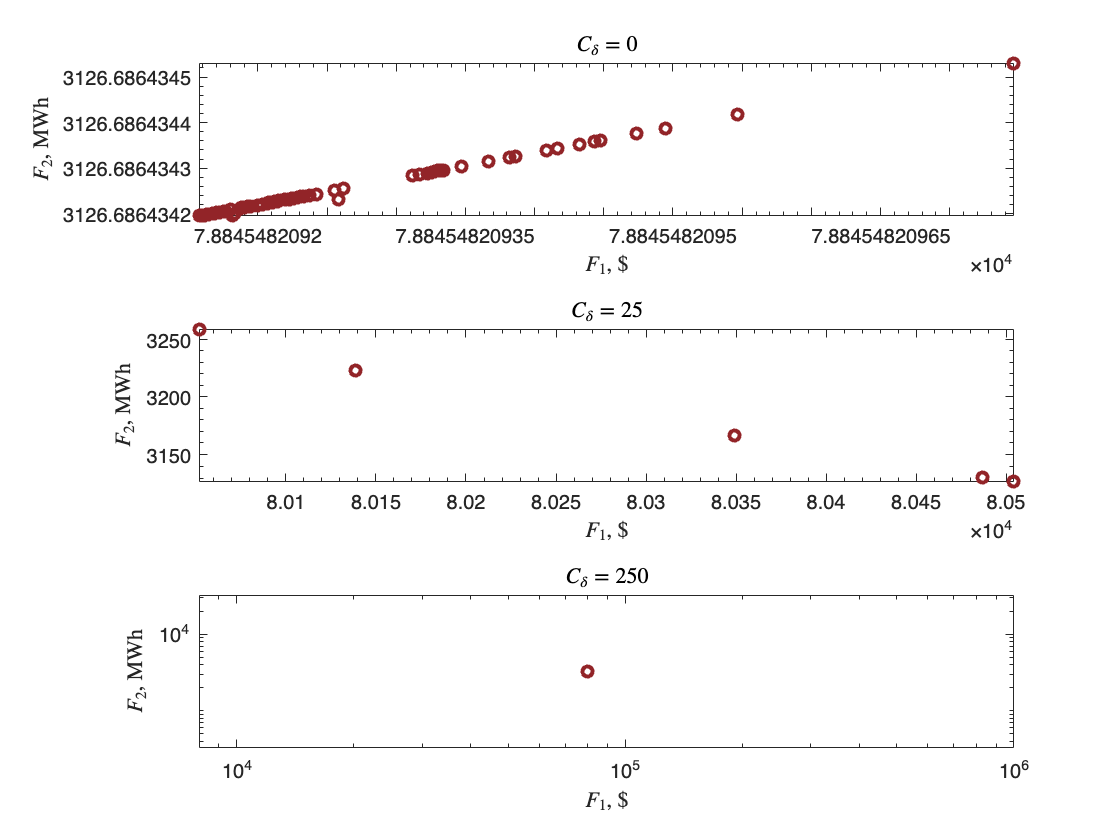

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb34e6789
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 81983.675820
Presolve removed 274 rows and 99 columns
Presolve time: 0.02s
Presolved: 1 rows, 3 columns, 3 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 78088.294135
Variable types: 2 continuous, 1 integer (1 binary)

Root relaxation

% Plot graph in process
tiledlayout(length(pens), 1)

% Do a full front for every penalty
for i = 1:length(pens)
    % Choose a penalty
    alpha = pens(i);

    for j = 1:length(span_pen)
        % Same as in the beginning but only for Gurobi
        w2 = span_pen(j);
        w1 = 1 - w2;
        network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
        network.Q_biobj = network.Q * w1;
        result_gurobi = solve_gurobi(network);
        [cost_gurobi_pen(j, 1), cost_gurobi_pen(j, 2)] = objective_values(network, alpha, result_gurobi.x);
    end  

    % Plot penalty front
    nexttile
    loglog(cost_gurobi_pen(:, 1), cost_gurobi_pen(:, 2), 'o', 'MarkerSize', 5, 'LineWidth', 2, 'Color', gurobi_color)
    title(['$C_\delta = ', num2str(alpha), '$'], 'Interpreter', 'latex');
    xlabel('$F_1$, \$', 'Interpreter','latex');
    ylabel('$F_2$, MWh', 'Interpreter','latex');
end

#### Refine the front

% Refresh penalty
alpha = 25;

% Calculate Euclidean distances between front points
distances = sqrt(sum(diff(cost_gurobi).^2, 2));

% Find the index of the largest gap
[~, largest_gap_index] = max(distances);

% Points forming the largest gap
point1 = span(largest_gap_index);
point2 = span(largest_gap_index + 1);

% Span for uniform weights
span_ref = linspace(point1, point2);

% Placeholders for costs
cost_gurobi_ref = zeros(length(span_ref), 2);

for i = 1:length(span_ref)
        % Same as in the beginning but only for Gurobi
        w2 = span_ref(i);
        w1 = 1 - w2;
        network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
        network.Q_biobj = network.Q * w1;
        result_gurobi_ref = solve_gurobi(network);
        [cost_gurobi_ref(i, 1), cost_gurobi_ref(i, 2)] = objective_values(network, alpha, result_gurobi_ref.x);
end  

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc35c3c7d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.320000e+11
Presolve removed 259 rows and 73 columns
Presolve time: 0.00s
Presolved: 16 rows, 29 columns, 50 nonzeros
Presolved model has 12 quadratic objective terms
Found heuristic solution: objective 20966.242339
Variable types: 16 continuous, 13 integer (13 binary)
Found heu

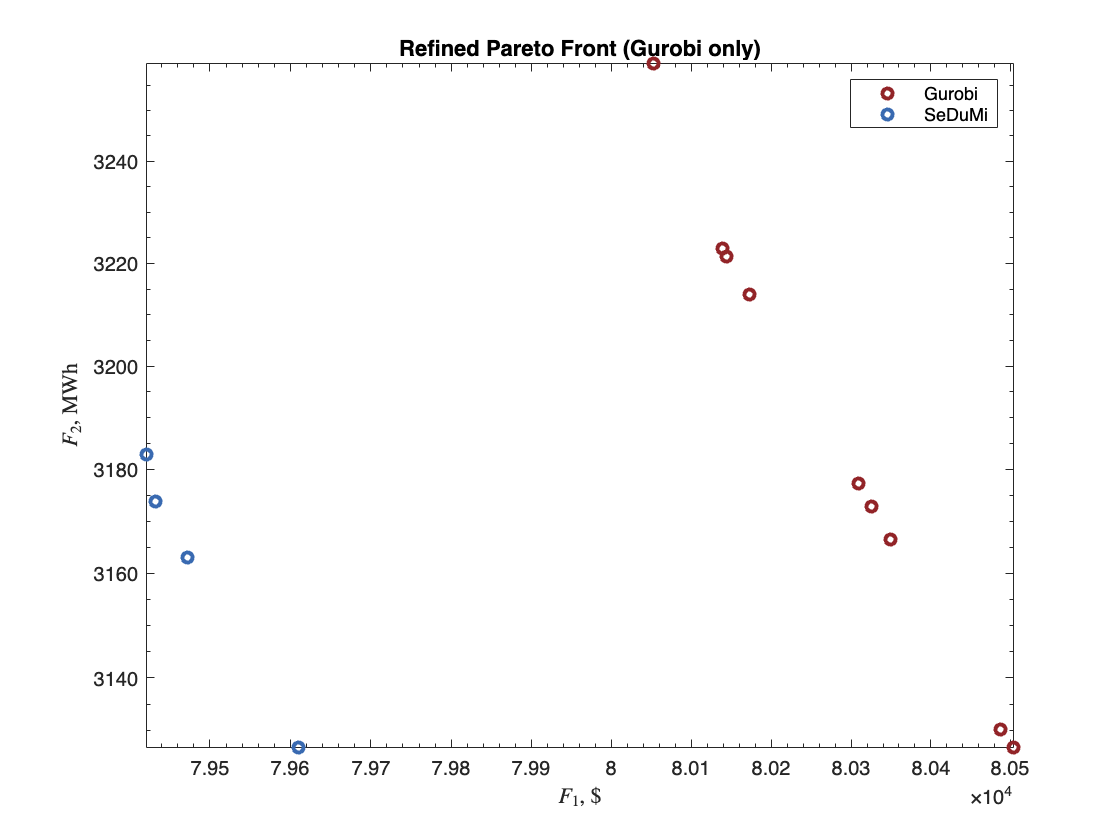

cost_gurobi_ref = [cost_gurobi_ref; cost_gurobi];

% Plot penalty front
figure();
figure();
loglog(cost_gurobi_ref(:, 1), cost_gurobi_ref(:, 2),'o', 'MarkerSize', 5, 'Color', gurobi_color, 'LineWidth', 2); hold on
loglog(cost_sedumi(:, 1), cost_sedumi(:, 2), 'o', 'MarkerSize', 5, 'Color', sedumi_color, 'LineWidth', 2); hold off
title('Refined Pareto Front (Gurobi only)');
legend('Gurobi', 'SeDuMi');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

## Wind and solar generation plots (24H)

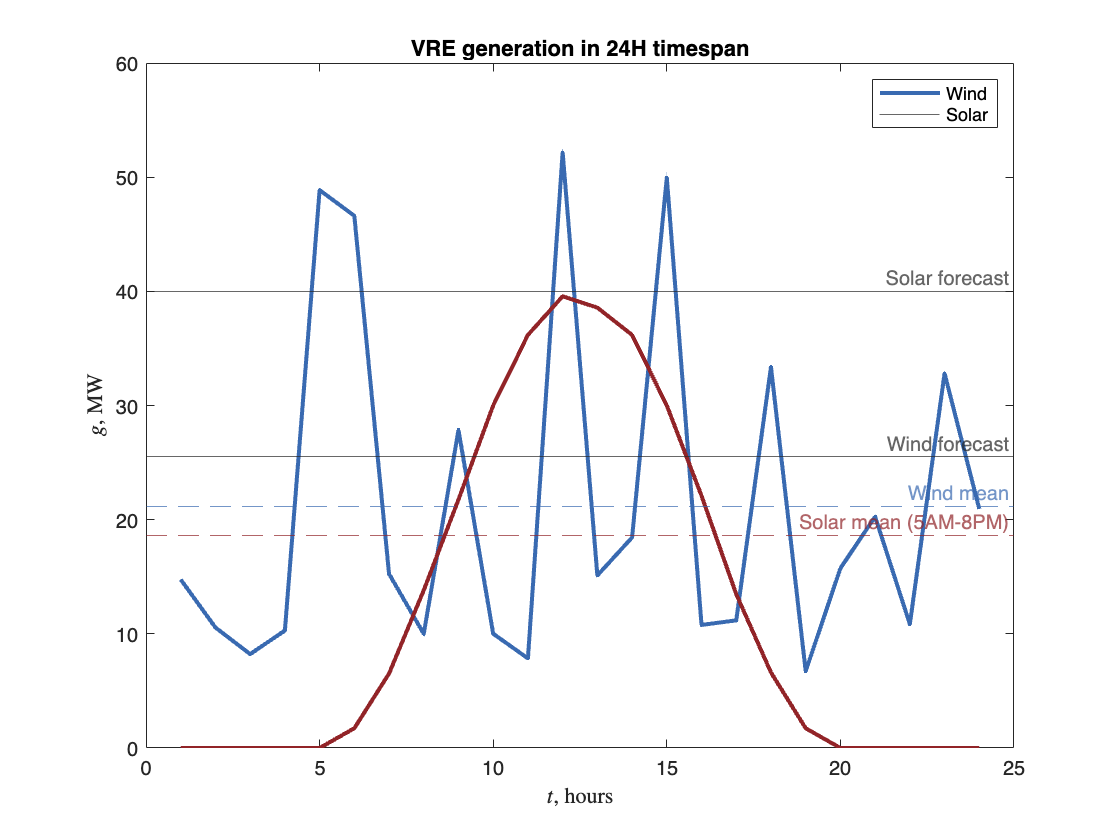

x = linspace(1, 24, 24);
wind_power = zeros(1, 24);
solar_power = zeros(1, 24);
for t = 1:24
    wind_power(t) = pdf(t, "wind");
    solar_power(t) = pdf(t, "solar");
end

figure()
plot(x, wind_power, Color=sedumi_color, LineWidth=2); hold on
yline(25.5,'-','Wind forecast');
yline(mean(wind_power),'--','Wind mean', Color=sedumi_color);
plot(x, solar_power, Color=gurobi_color, LineWidth=2); hold off
yline(40,'-','Solar forecast');
yline(mean(solar_power(5:20)),'--','Solar mean (5AM-8PM)', Color=gurobi_color);
title('VRE generation in 24H timespan')
legend('Wind', 'Solar');
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$g$, MW', 'Interpreter','latex');

## Example of network demand

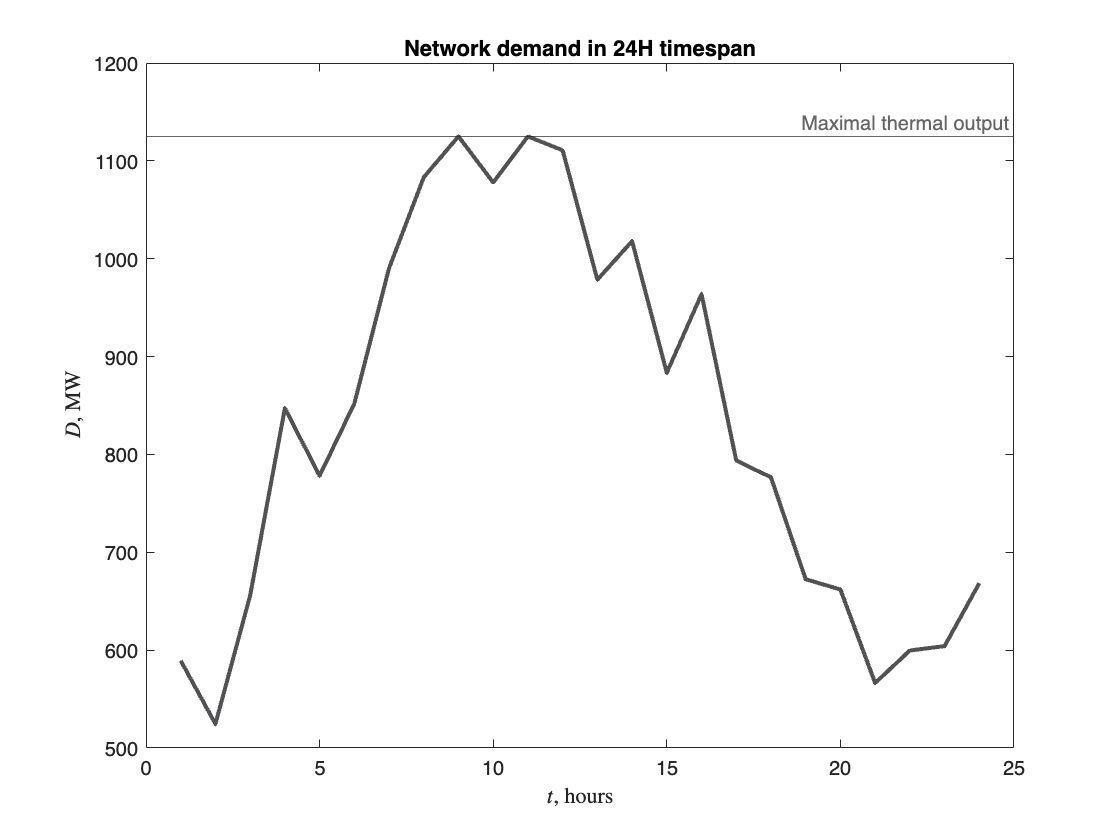

maxgen = [455, 455, 160, 55];
starting_state = [1, 1, 0, 0];
x = linspace(1, 24, 24);
demand_profile = demand(maxgen, starting_state, 24);

figure()
plot(x, demand_profile, LineWidth=2, Color=demand_color);
yline(sum(maxgen),'-','Maximal thermal output');
title('Network demand in 24H timespan')
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');